# **Econometrics 2 (Fall 2021)**

## **Jordan Holbrook**

## **Homework 5: Ordered Probit.**

Due Friday on Oct. 8th, 2021.

This code estimates, using maximum likelihood, the latent variable model

                                                                
$$y_i = \beta_1 x_i + u_i \text{ ,}$$


                                                                
$$z_i = \begin{cases} 0 &\text{if } y_i < \gamma_0 \\ 1 &\text{if }  \gamma_0 \leq y_i <  \gamma_1 \\ 2 & \text{ if } y_i  \geq  \gamma_1\end{cases} \text{ ,}$$
 

where $z_i$ is observed and $y_i$ is latent with $\gamma_0 < \gamma_1 \text{ ,}$ $u_i \sim NID(0,\sigma^2)$ and $\sigma=1$.

## Set the parameters.

There are 50 simulations with 300 observations per simulation. Set $\beta_0 = 0.5 \text{ and } \beta_1 = 3.$

clear
clc

global x z

N = 300;                                            % Number of observations.
beta1 = 3;                                        % Coefficient on X.
gamma0 = -1;                                       % First cutoff.
gamma1 = 1;                                       % Second cutoff.

if gamma1 <= gamma0
    error('Need gamma0 < gamma.\n')
end

sigma = 1;                                                                  % Standard deviation.

sim = 50;                                                                   % Number of simulations.
results_mat = zeros(sim, 3);                                                 % Results matrix.

## Maximum Likelihood Estimation.

In each simulation, draw the error terms, $U$, from the standard normal distribution and generate the data, $X, Y$ and $Z$. Estimate the model using maximum likelihood and record the estimates.

x = ((1:N)'./N).*normrnd(0,1,N,1);
    
for s = 1:sim 

    % Generate the data.
  
    u = normrnd(0,sigma,N,1);
    y = beta1*x + u;
    
    z = double((gamma0 < y));
    z = z + double((y >= gamma1));
    
    % ML estimation.

    b0 = [0.5 -0.5 0.5];

    options = optimset('Display','off');
    [b_mle, ~, ~, ~, ~, hess] = fminunc('logl_order_prob', b0, options);

    results_mat(s, 1:size(results_mat,2)) = b_mle';
    vmat = inv(hess);

end

## Display the results of the last simulation.

The estimate and standard error (in parenthesis) of $\beta_1$ in the last simulation is:

fprintf(' %0.4f\n(%0.4f)\n',b_mle(1),sqrt(vmat(1,1)))

 3.7111
(0.3067)


The estimate and standard error (in parenthesis) of $\gamma_0$ in the last simulation is:

fprintf(' %0.4f\n(%0.4f)\n',b_mle(2),sqrt(vmat(2,2)))

 -1.2932
(0.1282)


The estimate and standard error (in parenthesis) of $\gamma_1$ in the last simulation is:

fprintf(' %0.4f\n(%0.4f)\n',b_mle(3),sqrt(vmat(3,3)))

 1.0420
(0.1121)


## Empirical results.

The average and standard deviation (in parenthesis) of $\beta_1$ is:

fprintf(' %0.4f\n(%0.4f)\n', mean(results_mat(:,1)), std(results_mat(:,1)))

 3.0471
(0.2568)


The average and standard deviation (in parenthesis) of $\gamma_0$ is:

fprintf(' %0.4f\n(%0.4f)\n', mean(results_mat(:,2)), std(results_mat(:,2)))

 -1.0255
(0.1189)


The average and standard deviation (in parenthesis) of $\gamma_1$ is:

fprintf(' %0.4f\n(%0.4f)\n', mean(results_mat(:,3)), std(results_mat(:,3)))

 1.0054
(0.0990)


## Plot the estimated coefficients from all simulations.

bins = 10;

Plot a histogram of $\beta_1$.

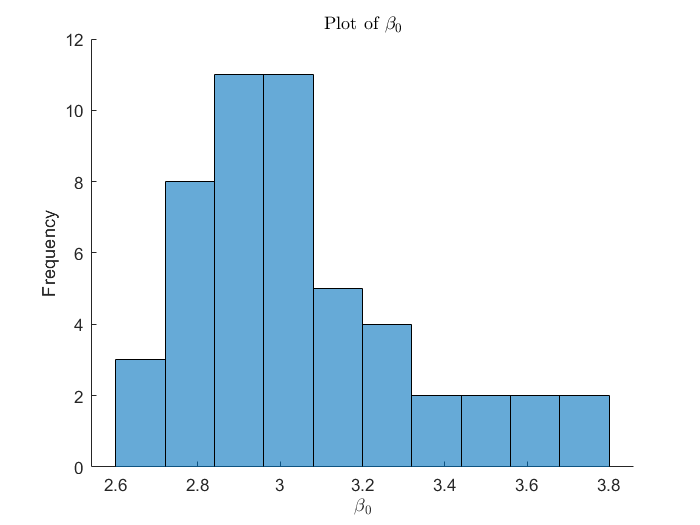

close all
figure(1)
hold on
histogram(results_mat(:,1),bins)
xlabel('$\beta_{0}$','interpreter','LaTex'); ylabel('Frequency')
title('Plot of $\beta_{0}$','interpreter','LaTex')
hold off

Plot a histogram of $\gamma_0$.

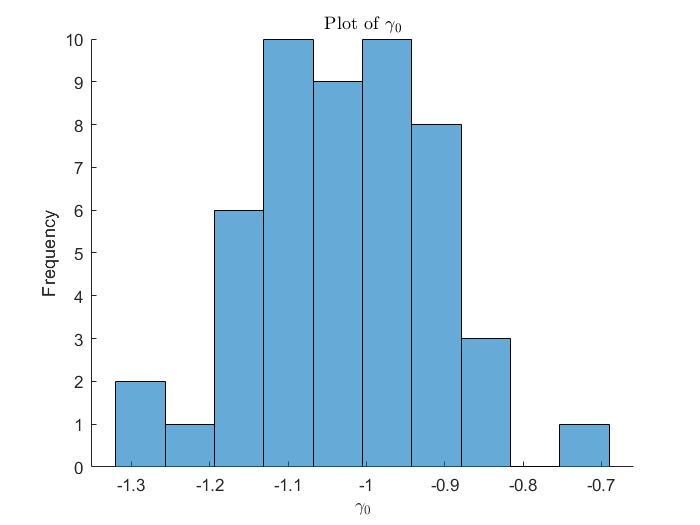

figure(2)
hold on
histogram(results_mat(:,2),bins)
xlabel('$\gamma_{0}$','interpreter','LaTex'); ylabel('Frequency')
title('Plot of $\gamma_{0}$','interpreter','LaTex')
hold off

Plot a histogram of $\gamma_1$.

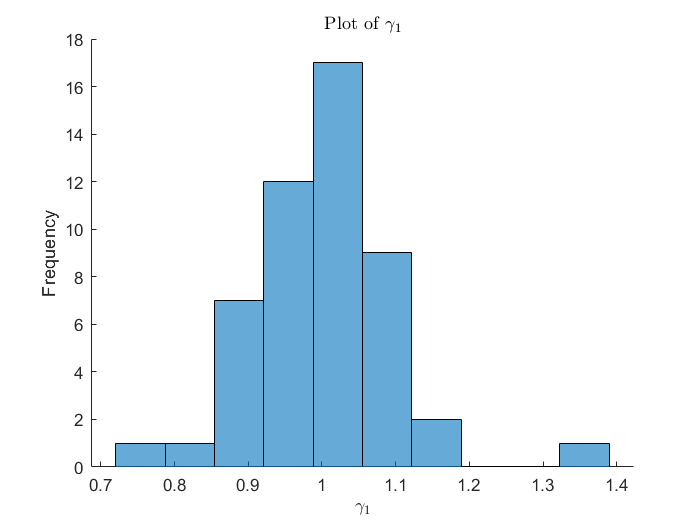

figure(3)
hold on
histogram(results_mat(:,3),bins)
xlabel('$\gamma_{1}$','interpreter','LaTex'); ylabel('Frequency')
title('Plot of $\gamma_{1}$','interpreter','LaTex')
hold off